A=imread('000837.jpg');
P=imread('000838.jpg');
figure,
subplot(2,2,1);imshow(A);title('Original Image at t');
subplot(2,2,3);imshow(P);title('Original Image at t+1');


A = rgb2gray(A);
P = rgb2gray(P);
subplot(2,2,2);imshow(A);title('Original Image:greyscale at t');
subplot(2,2,4);imshow(P);title('Original Image:greyscale at t+1');

compare = bitxor(A,P)
comp_thresh=imbinarize(compare,0.5)
figure,
imshow(comp_thresh)

%A=imread('000855.jpg');
%P=imread('000856.jpg');
[Result1,pre_thresh1] = xor_higherorder_bitplanes_merge_threshold('000831.jpg','000832.jpg')

Result1 = 694×1280 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

pre_thresh1 = 694×1280 uint8 matrix
    0    0    0    0    0    0   16   16   16   16    0    0   16    0   16    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   16    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0   48    0    0    0    0    0    0    0    0   48    0    0    0   16    0    0    0    0    0    0    0    0    0    0    0   16    0   48   48    0    0    0   16   16    0    0    0    0    0    0    0    0    0    0    0
   16   16   16   16    0   48   48    0    0    0    0    0    0   48   48   16   16    0    0    0    0    0    0   16    0    0    0    0    0    0    0   48    0    0    0    0    0    0    0    0    0    0    0   16   16   16   16   16   16   16
    0   16   16    0    0   48    0    0    0    0    0    0    0   48   48   16    0    0    0    0    0    0    0   16    0    0    0    0    0    0    0   48   48    0    0    0    0    0    0    0    0    0 

Result2 = xor_higherorder_bitplanes_merge_threshold('000832.jpg','000833.jpg')

Result2 = 694×1280 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

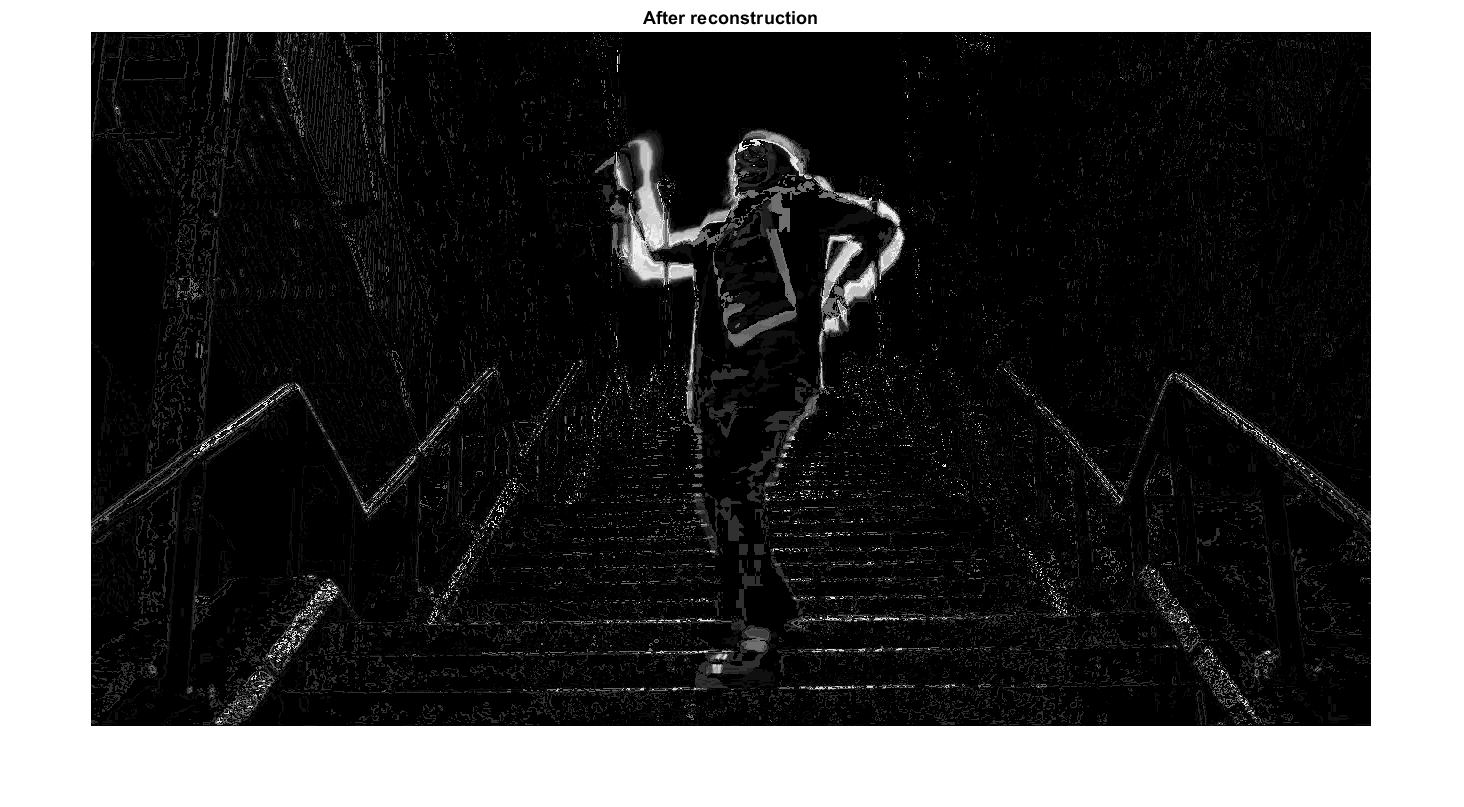


figure,
imshow(pre_thresh1);title('After reconstruction');

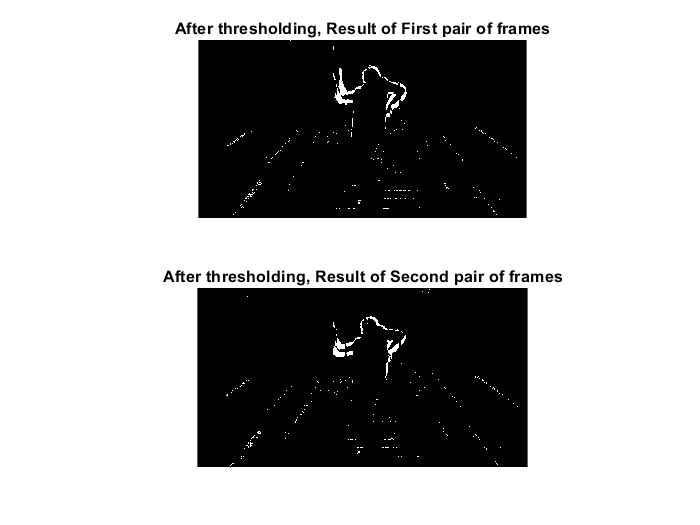


figure,
subplot(2,1,1);imshow(Result1);title('After thresholding, Result of First pair of frames');
imsave
subplot(2,1,2);imshow(Result2);title('After thresholding, Result of Second pair of frames');


diff_result = imabsdiff(Result1,Result2)

diff_result = 694×1280 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

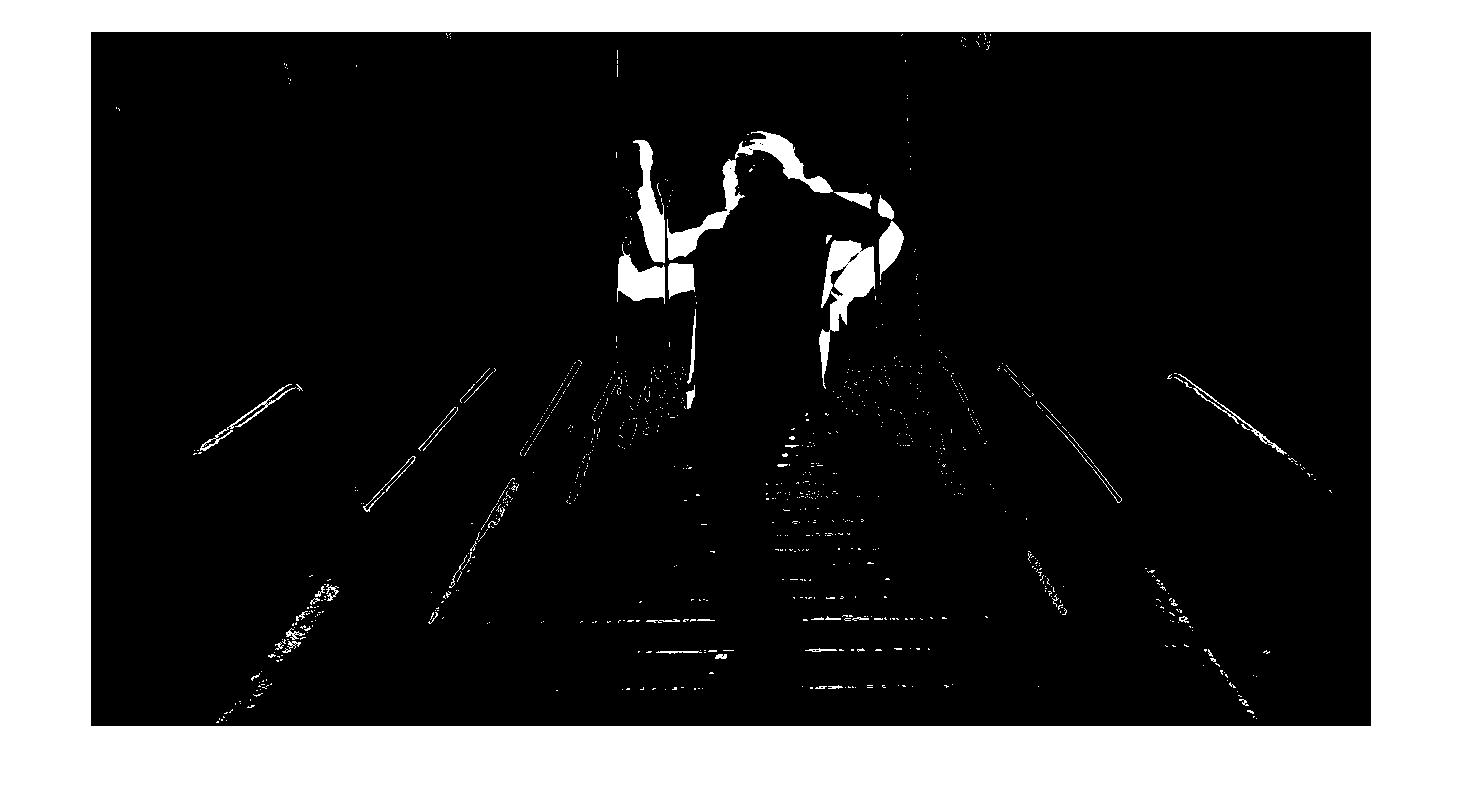

figure,
imshow(diff_result)

%Frame Differencing pictures
frame_diff= imabsdiff(rgb2gray(imread('000831.jpg')),rgb2gray(imread('000832.jpg')))

frame_diff = 694×1280 uint8 matrix
    1    0    0    1    4    9    7    1    2    4    1    5    6    1    6    6    4    5    8    1    4    3    1    2    8    3    0    1    2    2    2    6    2    1    3    4    3    3    3    3    1    1    1    0    1    1    1    1    3    3
    0    2    3    2    6   10    8    3    1    3    0    4    3    3    9   10    3    2    4    0    2    0    0    2    3    0    3    3    1    1    6   11    8    5    1    2    3    4    4    5    2    2    1    2    1    1    0    0    1    1
    3    4    3    3    7   12   10    4    1    1    0    2    1    8   13   12    2    0    0    2    0    3    2    2    3    1    1    1    1    0    5   10    4    2    0    2    3    2    0    1    3    4    4    5    5    6    6    6    6    6
    3    4    2    2    8   13   10    3    4    2    3    2    2   10   14   12    2    0    2    1    3    5    0    5    2    1    0    1    1    1    5    9    3    2    1    0    2    6   10   14   10   11  

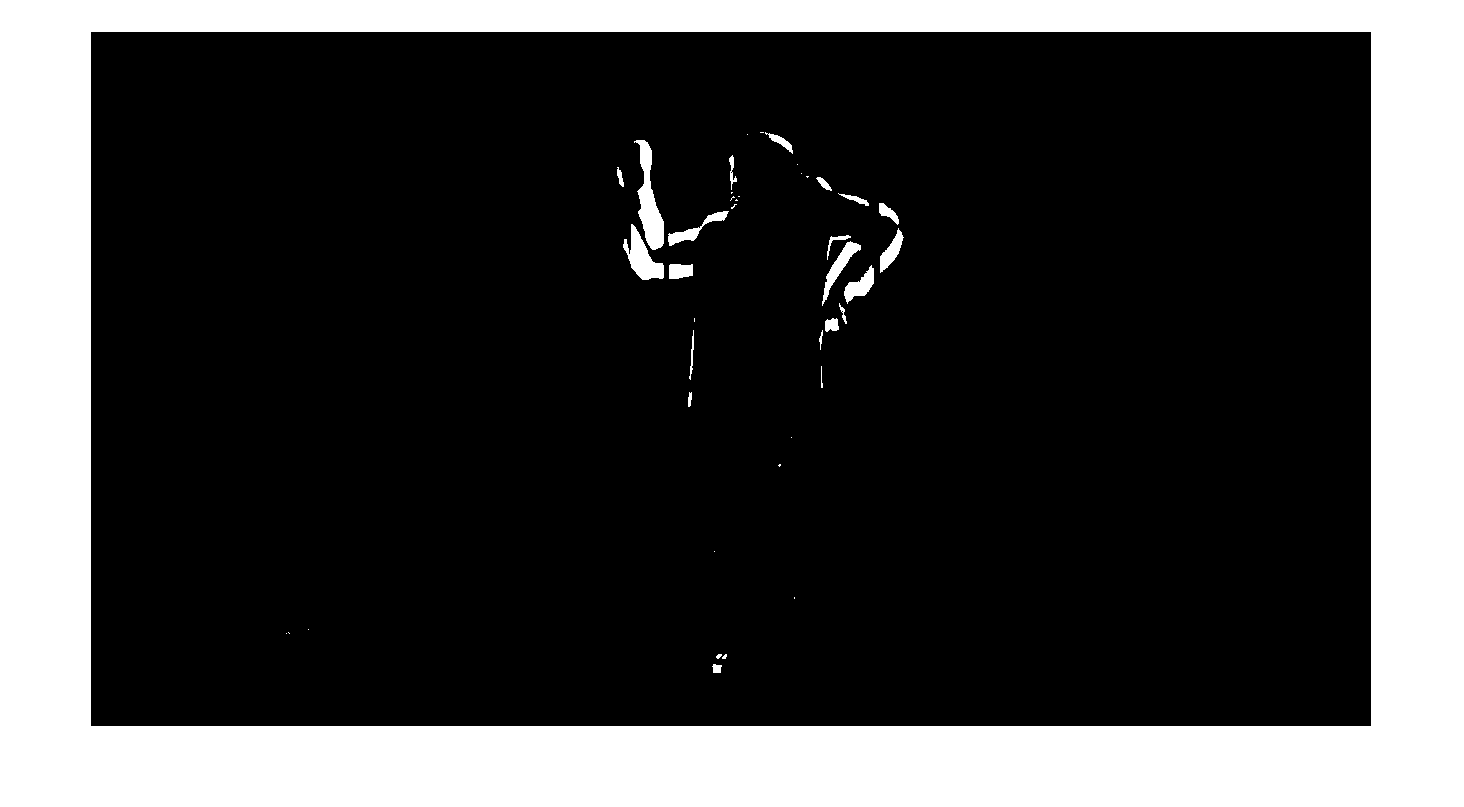


imshow(imbinarize(frame_diff,0.5))



% gray_000831=rgb2gray(imread('000831.jpg'))
% imshow(gray_000831)
% imsave
% gray_000832=rgb2gray(imread('000832.jpg'))
% imshow(gray_000832)
% imsave